## **Driver test program to check Clothoids library**

**Biarcs**

close all;
%figure('Position',[1,1,500,800]);

x0     = 0;
y0     = 0;
theta0 = 3.14*0.7;
x1     = 2;
y1     = 1;
theta1 = 3.14*0.1;
B1     = Biarc( x0, y0, theta0, x1, y1, theta1 );

x0     = -10;
y0     = 0;
theta0 = 3.14/4;
x1     = 2;
y1     = 1;
theta1 = 3.14*0.1;
B2     = Biarc( x0, y0, theta0, x1, y1, theta1 );

npts = 1000;

B1.rotate(pi/2,0,0);
B2.rotate(pi/2,0,0);

fmt1 = {'Color','red','LineWidth',3};
fmt2 = {'Color','black','LineWidth',3};
%B1.plot(npts,fmt1,fmt2);

hold on;

fmt1 = {'Color','blue','LineWidth',3};
fmt2 = {'Color','green','LineWidth',3};
%B2.plot(npts,fmt1,fmt2);

[C1,C2] = B1.getCircles();
[C3,C4] = B2.getCircles();

C1.intersect(C3)


ans =

  0×1 empty double column vector



C1.intersect(C4)

ans =    0.619711449004400


C2.intersect(C3)


ans =

  0×1 empty double column vector



C2.intersect(C4)

ans =    1.276503122179959


hold off;
C1.plot()
hold on;
C4.plot()

C1.info()

CircleArc
x0     = 0
y0     = 0
theta0 = 3.7688
k      = -1.51933
L      = 1.66304



C4.info()

CircleArc
x0     = -1.20978
y0     = -4.05915
theta0 = 1.18758
k      = 0.112684
L      = 6.18734




[s1,s2] = B1.intersect( B2 )

s1 =    0.619711449004400
   2.939542986160690


s2 =   10.471100711476428
  12.609108785232879


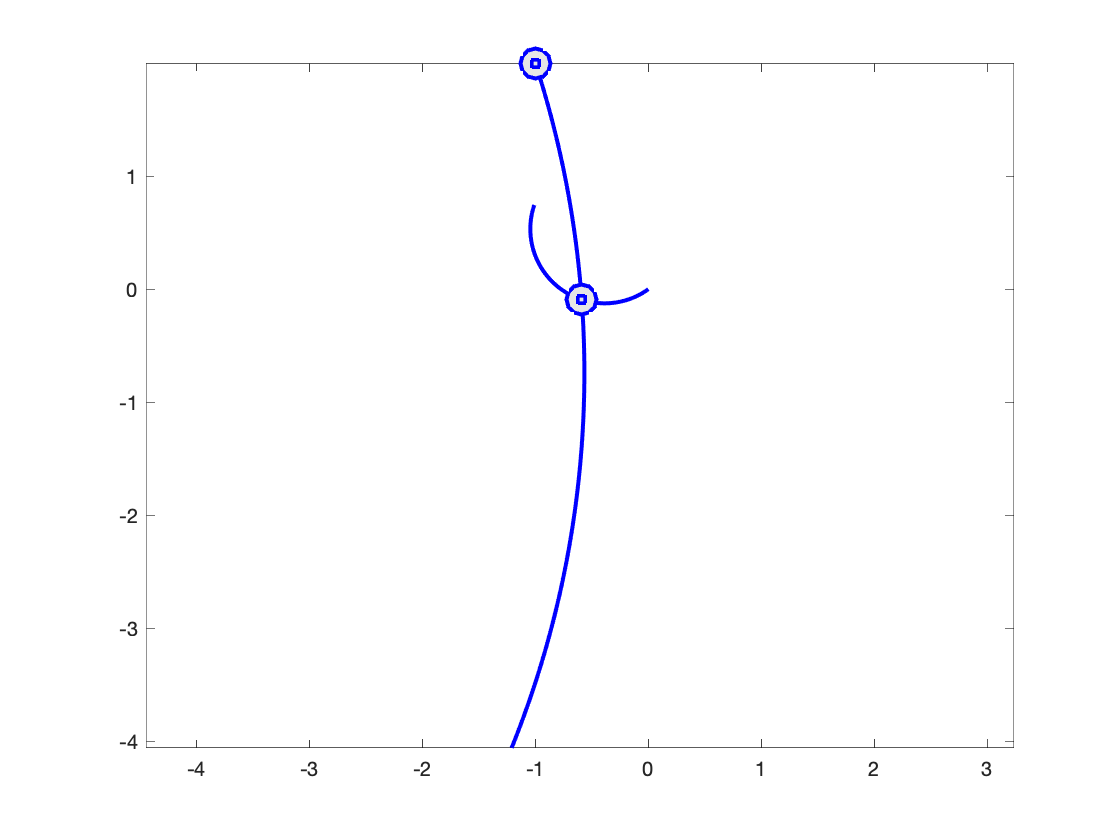


XY1 = B1.eval( s1 );
XY2 = B2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
plot( XY2(1,:), XY2(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',5,...
      'MarkerEdgeColor','b',...
      'MarkerFaceColor',[0.9,0.9,0.9] );

axis equal;